clear;clc;
%%%%%%%%%实验条件%%%%%%%%%
Rl=10;
Ll=0.00000001;
f0=1000000000;
Z0=50;
Y0=1/50;
%%%%%%%%%公式代入%%%%%%%%%
Zl0=Rl+Ll*f0*2*pi*1i

Zl0 = 10.0000 + 62.8319i

Yl0=1/Zl0;
gamma_l0=(Zl0-Z0)/(Zl0+Z0);
rou=(1+abs(gamma_l0))/(1-abs(gamma_l0));
%%%%%%%%%计算两组解%%%%%%%%%
[L11norm,L21norm,L12norm,L22norm] = matching_sstub(Z0,Zl0)%调用matching_sstub

$$L11norm = 0.3988$$

$$L21norm = 0.45358276986746659531490877270699$$

$$L12norm = 0.3127$$

$$L22norm = 0.04642$$

%%%%%%%%%计算频率范围与中心频点%%%%%%%%%
f=f0.*(0.6:0.001:1.4);
theta1=L11norm.*2.*pi.*(f./f0);
theta2=L21norm.*2.*pi.*(f./f0);
theta3=L12norm.*2.*pi.*(f./f0);
theta4=L22norm.*2.*pi.*(f./f0);
%%%%%%%%%输入阻抗初始化%%%%%%%%%
Zin11=zeros(1,801);
Zin1=zeros(1,801);
Zin12=zeros(1,801);
Zin2=zeros(1,801);
%%%%%%%%%获得不同频率下的各参数%%%%%%%%%
Zl=Rl+1i*Ll.*2.*pi.*f;
for j=1:801
    Zin11(j)=add_serline(Z0, theta1(j), Zl(j));
    Zin1(j) = add_parsstub(Z0, theta2(j), Zin11(j));
    Zin12(j)=add_serline(Z0, theta3(j), Zl(j));
    Zin2(j) = add_parsstub(Z0, theta4(j), Zin12(j));
end
gamma1=(Zin1-Z0)./(Zin1+Z0);
gamma2=(Zin2-Z0)./(Zin2+Z0);
amp1=20*log10(abs(gamma1));
amp2=20*log10(abs(gamma2));

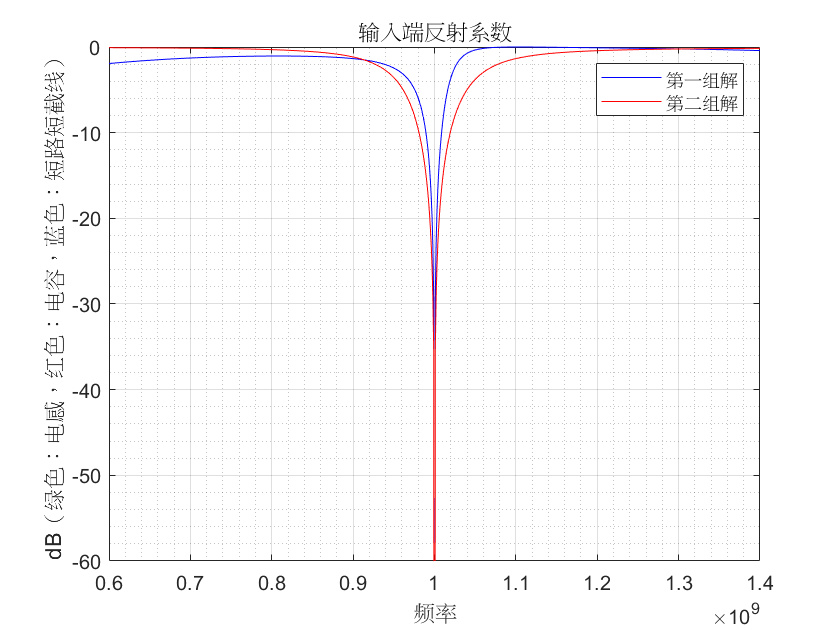

%% 反射系数频率响应曲线绘制
err = 1e-9;
%单分支并联短截线的两个解
figure(1);
plot(f,20*log10(abs(gamma1)+err),'b');    %第一解反射系数曲线模值频率特性
hold on;
plot(f,20*log10(abs(gamma2)+err),'r');    %第二解反射系数曲线模值频率特性
hold on;
%%%%%%%%%%%%%%%%%%%
title('输入端反射系数');
legend("第一组解","第二组解");
xlabel('频率');
ylabel('dB（绿色：电感，红色：电容，蓝色：短路短截线）');
ylim([-60 0]);
grid on; grid minor;

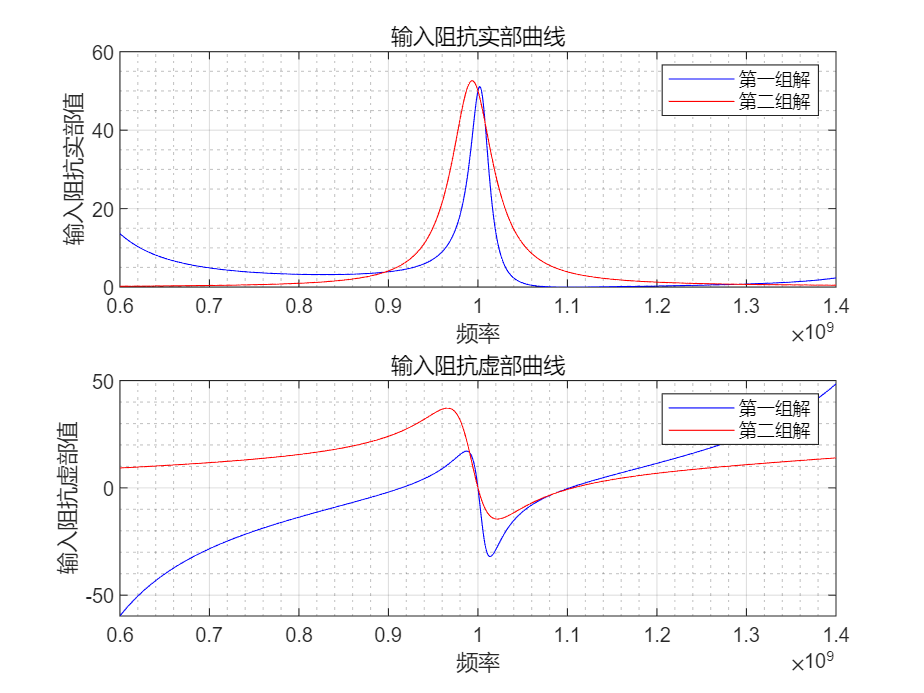

%% 输入阻抗频率响应曲线绘制
figure(2);
subplot(2,1,1);
plot(f,real(Zin1),'b');                     %输入阻抗实部频率特性
hold on
plot(f,real(Zin2),'r'); 
%%%%%%%%%%%%%%%%%%%
title('输入阻抗实部曲线');
legend("第一组解","第二组解");
xlabel('频率');
ylabel('输入阻抗实部值');
grid on; grid minor;
subplot(2,1,2)                                 %输入阻抗虚部频率特性
plot(f,imag(Zin1),'b'); 
hold on
plot(f,imag(Zin2),'r'); 
%%%%%%%%%%%%%%%%%%%
title('输入阻抗虚部曲线');
legend("第一组解","第二组解");
xlabel('频率');
ylabel('输入阻抗虚部值');
grid on; grid minor;

- **函数matching_sstub**

function [L11norm,L21norm,L12norm,L22norm] = matching_sstub(Z0,Zl0)
syms x1 x2;
gamma_0=(Zl0-Z0)/(Zl0+Z0);
phase=angle(gamma_0);
length_0=phase/4/pi+1/4;%负载与第一个波节点的距离（归一化波长）
rou=(1+abs(gamma_0))/(1-abs(gamma_0));
eq1=(x1-rou.^2.*x1)./(1+rou.^2.*(x1.^2))-x2;
eq2=(rou+rou.*(x1.^2))./(1+rou.^2.*(x1.^2))-1;
[x1,x2]=solve(eq1,eq2,x1,x2);
x3(1)=vpa(x1(1),4);
x3(2)=vpa(x1(2),4);
x4(1)=vpa(x2(1),4);
x4(2)=vpa(x2(2),4);
L11norm=length_0+atan(x3(1))/2/pi;
L21norm=acot(x4(1))/2/pi;
L12norm=length_0+atan(x3(2))/2/pi;
L22norm=acot(x4(2))/2/pi;
L11norm=vpa(L11norm,4);
L12norm=vpa(L12norm,4);
L21norm=vpa(L21norm,4);
L22norm=vpa(L22norm,4);
if L11norm>=0.5 L11norm=L11norm-0.5;
end
if L12norm>=0.5 L12norm=L11norm-0.5;
end
if L21norm>=0.5 L21norm=L11norm-0.5;
end
if L22norm>=0.5 L22norm=L11norm-0.5;
end
if L11norm<0 L11norm=L11norm+0.5;
end
if L12norm<0 L12norm=L12norm+0.5;
end
if L21norm<0 L21norm=L21norm+0.5;
end
if L22norm<0 L22norm=L22norm+0.5;
end
end

- **函数add_serline**

function Zin = add_serline(Z0, theta, ZL)
Zin=Z0.*(ZL.*cos(theta)+Z0.*sin(theta)*1i)./(Z0.*cos(theta)+ZL.*sin(theta)*1i);
end

- **函数add_parsstub**

function Zin = add_parsstub(Z0, theta, ZL)
Zin1 = Z0.*1i.*tan(theta);
Zin = Zin1.*ZL./(Zin1 + ZL);
end